load('net.mat')
load('test_data1_cell.mat');
%load('test_data1.mat');

net = net;

% Setting up plotting parameters
start = 1;
numSimulations = 50;
data = test_data1_cell;
%data11 = test_data1;

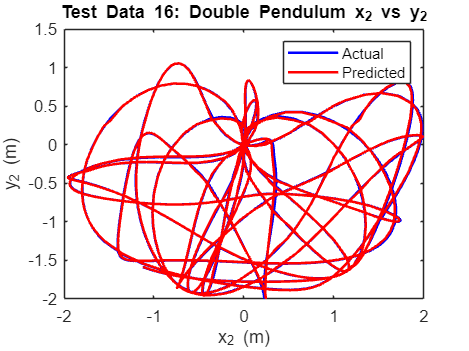

% Loop the plotting through the specified simulations
for i = 16%start:numSimulations  
    % Extracting data for the current simulation
    time = data{i, 1};
    theta1 = data{i, 2};
    theta2 = data{i, 3};
    omega1 = data{i, 4};
    omega2 = data{i, 5};
    x1 = data{i, 6};
    y1 = data{i, 7};
    x2 = data{i, 8};
    y2 = data{i, 9};
     
    % Transposing the data     
    inputTheta1 = theta1';
    inputTheta2 = theta2';
    inputOmega1 = omega1';
    inputOmega2 = omega2';
    inputX1     = x1';
    inputY1     = y1';
    inputX2     = x2';
    inputY2     = y2';

    % Making predictions using the neural network       
    predictedTheta1 = predict(net, {inputTheta1});
    predictedTheta2 = predict(net, {inputTheta2});
    predictedOmega1 = predict(net, {inputOmega1});
    predictedOmega2 = predict(net, {inputOmega2});
    predictedX1     = predict(net, {inputX1});
    predictedY1     = predict(net, {inputY1});
    predictedX2     = predict(net, {inputX2});
    predictedY2     = predict(net, {inputY2});
   
    % Converting predicted data to matrices   
    newPredictedTheta1 = cell2mat(predictedTheta1);
    newPredictedTheta2 = cell2mat(predictedTheta2);
    newPredictedOmega1 = cell2mat(predictedOmega1);
    newPredictedOmega2 = cell2mat(predictedOmega2);
    newPredictedX1     = cell2mat(predictedX1);
    newPredictedY1     = cell2mat(predictedY1);
    newPredictedX2     = cell2mat(predictedX2);
    newPredictedY2     = cell2mat(predictedY2);
    


    % Plotting the trajectories of actual and predicted
    % Create a figure    
    figure;  
    % Extracting actual and predicted data for plotting
    x2_actual = x2; 
    y2_actual = y2;   
    x2_predicted = newPredictedX2; 
    y2_predicted = newPredictedY2;
    % Plotting actual and predicted trajectories
    plot(x2_actual, y2_actual, 'b', 'LineWidth', 1.5);
    hold on; 
    plot(x2_predicted, y2_predicted, 'r', 'LineWidth', 1.5);          
    xlabel('x_{2} (m)');
    ylabel('y_{2} (m)');
    title(['Test Data ', num2str(i), ': Double Pendulum x_{2} vs y_{2}']);
    legend('Actual', 'Predicted'); 
    hold off; 
end

% Saving all figures into a single MAT-file
save('DP_Trajectory_figures.mat', 'figHandles');

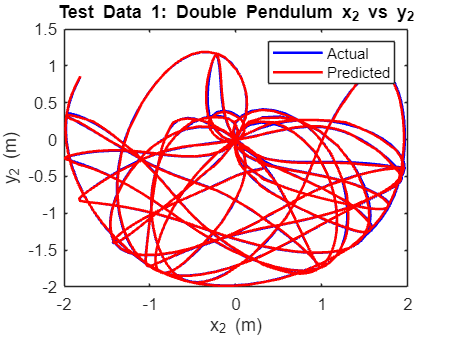

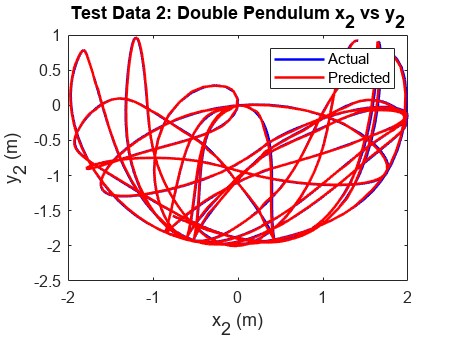

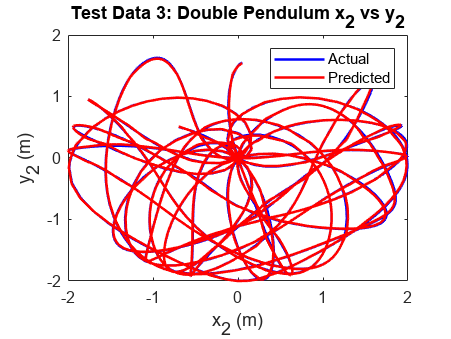

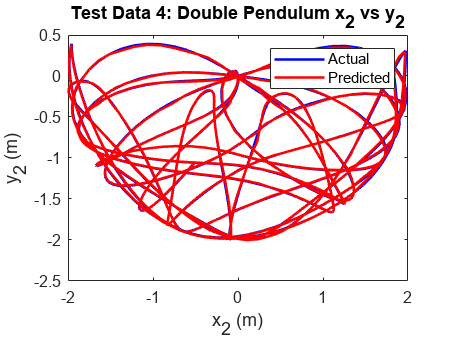

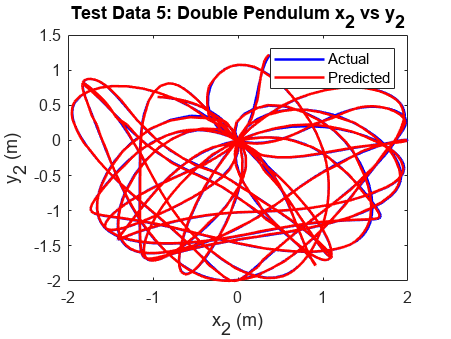

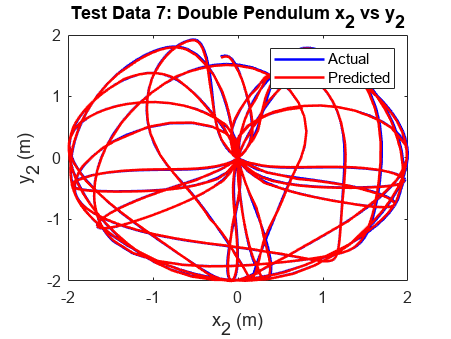

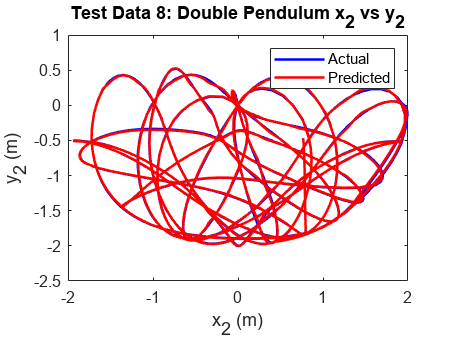

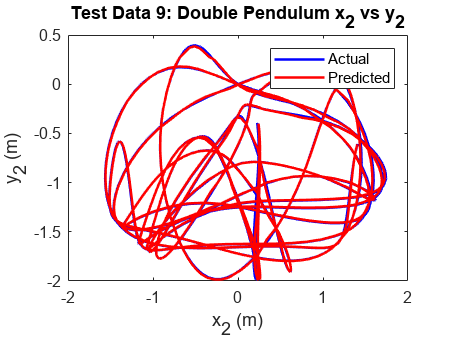

% To load the figures:
% 1. Loading the MAT-file
loadedData = load('DP_Trajectory_figures.mat');

% 2. Access the figure handles
loadedFigHandles = loadedData.figHandles;

% 3. Display the figures
for i = start:numSimulations
    figure(loadedFigHandles{i});
end